# Proyecto 3 - Modelado de Mecánica Celeste

Por: Asli Alejandra Sandoval Vega, Alexis Sánchez Orosco, Santiago Flores Larrondo

*Algoritmos Numéricos por Computadora*

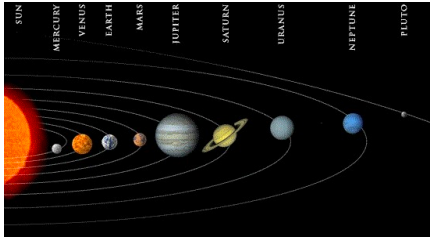

## Problema a resolver

Responder preguntas interesantes sobre el sistema solar y su movimiento requiere modelar este sistema mediante ecuaciones que describan estos movimientos con el paso del tiempo. Para lograr esta tarea, modelaremos el sistema solar usando ecuaciones diferenciales, las cuales nos ayudarán a describir el movimiento de los planetas respecto al Sol con el paso del tiempo. 

Una vez que que se tengan las ecuaciones, el sistema bien definido y resuelto por algún metodo de ODEs de segundo grado, podremos responder a las siguientes preguntas o problemas específicos:

- ¿Cual es la distancia mínima y máxima de un planeta hacia el Sol?

-  ¿Cuándo estará Marte más cerca a la Tierra en los próximos 10 años? ¿Cuál es esta distancia mínima?

En general, debemos ser capaces de usar nuestro modelo para realizar cálculos y predicciones sobre el sistema solar con el paso del tiempo. 

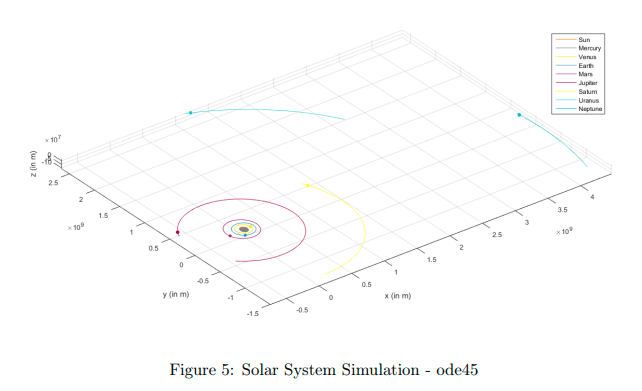

## Modelo matemático

El movimiento de los planetas en el sistemas solar se describe con ecuaciones diferenciales, ya que este sistema es dinámico con el paso del tiempo, dependiendo de las masas de los planetas y sus posiciones. Dicho movimiento se describe mediante una elipse y con un movimiento de fuerzas entre dos cuerpos. En este caso, se visualiza el movimiento como producto de la fuerza ejercida entre algún planeta y el Sol.  

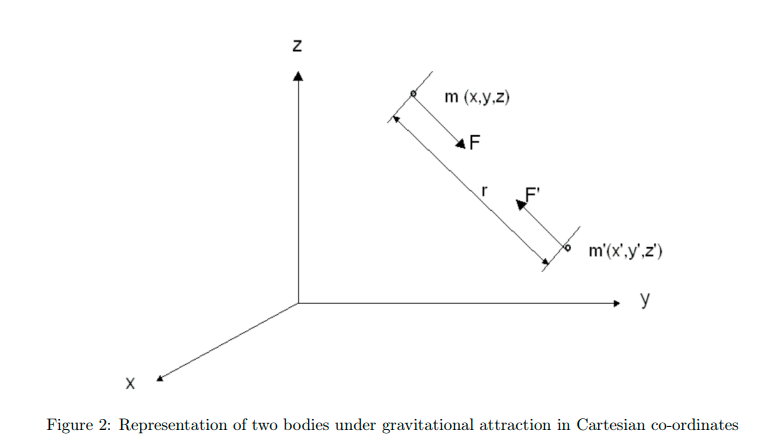

De acuerdo a esta imagen, observamos que se puede modelar el movimiento planetario con las fuerzas entre ambos cuerpos de acuerdo a la Ley de Gravitación de Newton. En la siguiente imagen, podemos visualizar la fuerza que ejerce un cuerpo sobre otro y viceversa. 

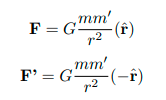

Para hacer un modelado de acuerdo a las coordenadas de los planetas, se descompone la fuerzas en sus tres componentes y aplicamos la segunda ley de Newton. 

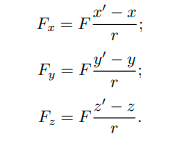    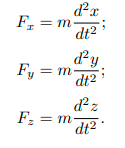

Haciendo una combinación de las ecuaciones, obtenemos como resultado las ecuaciones diferenciales respecto a x, y, z usando las posiciones de los cuerpos y sus masas. De esta manera, tenemos ecuaciones de segundo orden que nos permiten modelar el movimiento planetario.  

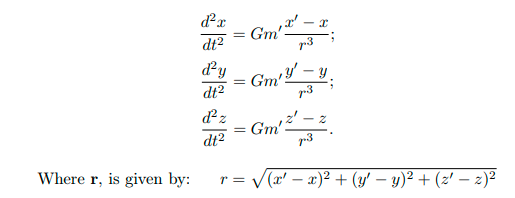

Podemos ahora usar las ecuaciones diferenciales de segundo orden para diseñar un sistema general de ecuaciones que describan el movimiento de varios planetas respecto a otro cuerpo (el Sol en nuestro caso).

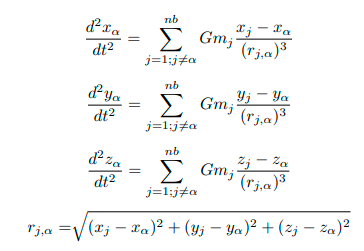

En dicho sistema, tenemos una ecuación diferencial que describe el movimiento en x, y, z  de nb cuerpos, respecto a un cuerpo alpha en el tiempo. Tambien se involucra la distancia entre los cuerpos y la masa de estos, junto con la constante de gravitación G. 

A este sistema de ecuaciones le llamaremos Problema de Valor Inicial y se puede representar como un vector de posiciones y velocidades iniciales. 

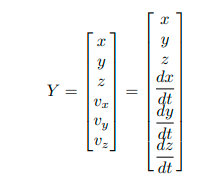

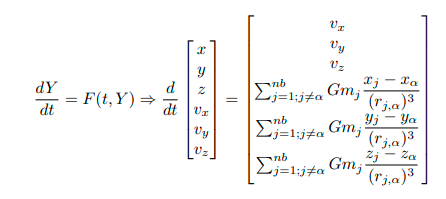

Para nuestro modelado del movimiento planetario, usaremos los datos, del 6 de abril del 2018, de posición y velocidad, obtenidos del sistema Horizon.

#### Tabla 1:

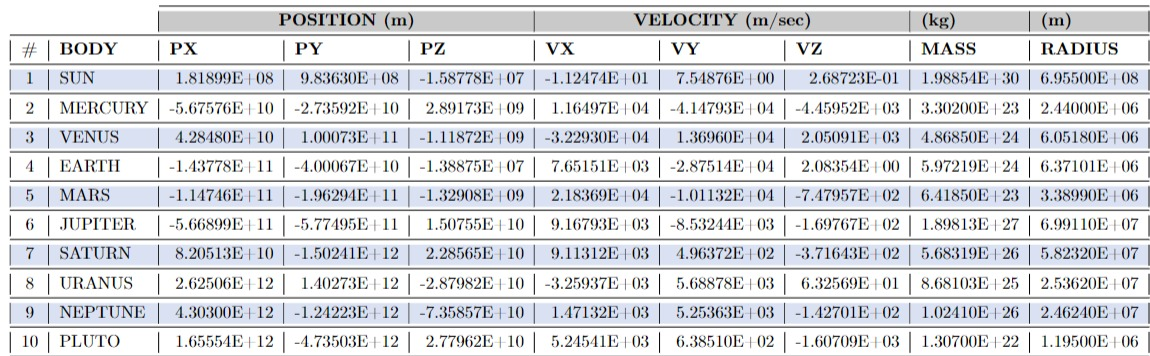

Por lo tanto, se cuentan con las nueves ecuaciones diferenciales que caracterizan el sistema solar: 8 planetas y el sol. Las ecuaciones describen el movimiento de los planetas respecto al Sol, así como el movimiento del Sol con sí mismo. La solución del sistema de ecuaciones que describen este movimiento de cuerpos respecto al Sol serán las que nos describan de manera analítica la dinámica descrita por el sistema. Usaremos algunos métodos de solución de ecuaciones diferenciales de segundo grado como ode45, RK4, ABM4 y RKF45 para resolver este sistema. Analizaremos el tiempo que tarda en resolver cada uno de estos métodos, ante la presencia de múltiples ecuaciones en un mismo sistema. 

## Referencias

*"THE EQUATIONS OF PLANETARY MOTION AND THEIR NUMERICAL SOLUTION"* escrito por Jonathan Njeunje, Dinuka Sewwandi de Silva. Mayo 7, 2018. 

## Solución propuesta al modelo

Y= [x ;y ;z ;Vx; Vy; Vz]

Donde Gm es el parámetro gravitacional estándar (el producto de la constante de gravitación universal y su masa). El vector comprende las Gm`s de todos los planetas del sistema solar en este orden: Sol, Mercurio, Venus, Tierra, Marte, Júpiter, Saturno, Urano y Neptuno. 

Acerca del vector Y0: del índice 1 a 27 se encuentran guardadas las posiciones en sus componentntes X, Y, Z, i.e., Y0[1]=Xsol, Y0[2]=Ysol, Y0[3]=Zsol, Y0[4]= Xmercurio, ....

A partir del índice 28 encontramos las velocidades en sus componentes X, Y, Z, i.e., Y0[28]=VxSol, Y0[29]=VySol, Y0[30]= VzSol. 

Los valores tanto de posiciones como de velocidades se pueden revisar en la **Tabla 1** obtenidos del sistema Horizon. 

Gm=[1.32712440018e20;2.2032e13;3.24859e14;3.986044418e14;4.282837e13;1.26686534e17;
    3.7931187e16;5.793939e15;6.836529e15];

r0=[1.81899e8;9.83630e8;-1.58778e7;
    -5.67576e10;-2.73592e10;2.89173e9;
    4.28480e10;1.00073e11;-1.11872e9;
    -1.43778e11;-4.00067e10;-1.38875e7;
    -1.14746e11;-1.96294e11;-1.32908e9;
    -5.66899e11;-5.77495e11;1.50755e10;
    8.20513e10;-1.50241e12;2.28565e10;
    2.62506e12;1.40273e12;-2.87982e10;
    4.30300e12;-1.24223e12;-7.35857e10];
v0=[-1.12474e01 ; 7.54876e00 ; 2.68723e-01;
    1.16497e04 ; -4.14793e04 ; -4.45952e03;
    -3.22930e04 ; 1.36960e04 ; 2.05091e03;
    7.65151e03; -2.87514e04 ; 2.08354e00;
    2.18369e04 ; -1.01132e04 ; -7.47957e02;
    9.16793e03 ; -8.53244e03 ; -1.69767e02;
    9.11312e03 ; 4.96372e02 ; -3.71643e02;
    -3.25937e03 ; 5.68878e03 ; 6.32569e01;
    1.47132e03 ; 5.25363e03 ; -1.42701e02];

Nuestra y0 seran las posiciones iniciales de cada planeta, asi como sus velocidades:

y0=[r0;v0];
 
fPlanetas=@(t,y)aceleracionPlanetas(Gm,y);

Definimos una h en tamaño de segundos para asi graficar los 365 días del año o incluso poder graficar para mayor cantidad de años

h = 60*60*24;
tf= 365*h;

Resolvemos con RK4 y graficamos los ejes x, y para visualizar las posiciones de los planetas a un año

%Medimos el tiempo que tarda RK4 en resolver
tic
[t1,y1]=RK4_se(fPlanetas,0,tf,y0,h)

t1 =            0       86400      172800      259200      345600      432000      518400      604800      691200      777600      864000      950400     1036800     1123200     1209600     1296000     1382400     1468800     1555200     1641600     1728000     1814400     1900800     1987200     2073600     2160000     2246400     2332800     2419200     2505600     2592000     2678400     2764800     2851200     2937600     3024000     3110400     3196800     3283200     3369600     3456000     3542400     3628800     3715200     3801600     3888000     3974400     4060800     4147200     4233600


y1 = 1.0e+12 *

    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010   

toc

Elapsed time is 0.098602 seconds.



%Medimos el tiempo que tarda ABM4 en resolver
tic
[t2,y2]=abm4(fPlanetas,y0,0,tf,h);
toc

Elapsed time is 0.023843 seconds.



%Medimos el tiempo que tarda ode45 en resolver
tic
[t3,y3]=ode45(fPlanetas,[0 tf],y0);
toc

Elapsed time is 0.008269 seconds.



%Medimos el tiempo que tarda ode113 en resolver
tic
[t4,y4]=ode113(fPlanetas,[0 tf],y0);
toc

Elapsed time is 0.010896 seconds.



%Medimos el tiempo que tarda RKF45 en resolver
tic
[t5,y5]=odeRKF45(fPlanetas,0,tf,y0,h);
toc

Elapsed time is 0.047963 seconds.



%Medimos el tiempo que tarda ABM4 optimizado en resolver
tic
%[t6,y6]=ABM4o(fPlanetas,y0,0,tf,h);
toc

Elapsed time is 0.000825 seconds.


Por lo tanto, vemos que el método ode45 es aquél que tarda menos tiempo en resolver el sistema. En segundo lugar está el ABM4 y ABM4o y finalmente el ode113, RK4 y RKF45 son aquellos que mas tiempo tardan en resolver. 

***Graficamos para un año***


planetas=["Sol", "Mercurio", "Venus", "Tierra", "Marte", "Júpiter", "Saturno", "Urano", "Neptuno"];
n=length(y1(:,1))

n = 54

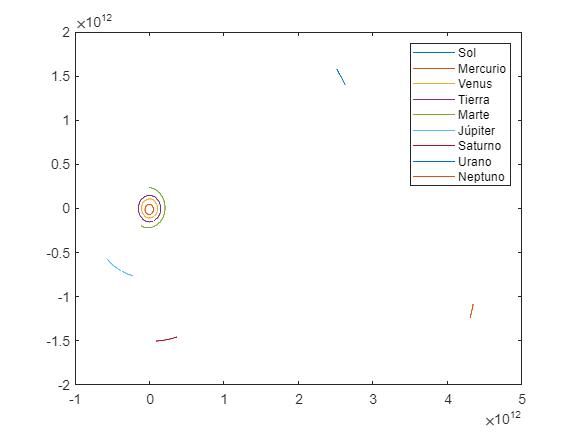


for i=1:3:n/2-2
    if i>1
        plot(y1(i,:),y1(i+1,:),'DisplayName',planetas((i-1)/3))
    else
        plot(y1(i,:),y1(i+1,:),'DisplayName',planetas(1))
    end
    hold on
end
legend("Sol", "Mercurio", "Venus", "Tierra", "Marte", "Júpiter", "Saturno", "Urano", "Neptuno")
hold off

## Problemas a resolver

### Problema 1

Elegir un planeta y encontrar su distancia mínima y máxima al Sol. 

Solución: Crear el sistema para 100 años y ver la distancia mínima y máxima. Elegimos a Mercurio 

***Cálculo a 100 años***

h = 60*60*24

h = 86400

tf= 365*h*100; %usamos una h por 100 para el número de años
[t1,y1]=RK4_se(fPlanetas,0,tf,y0,h);

%Graficamos para 100 años

planetas=["Sol", "Mercurio", "Venus", "Tierra", "Marte", "Júpiter", "Saturno", "Urano", "Neptuno"];
n=length(y1(:,1))

n = 54

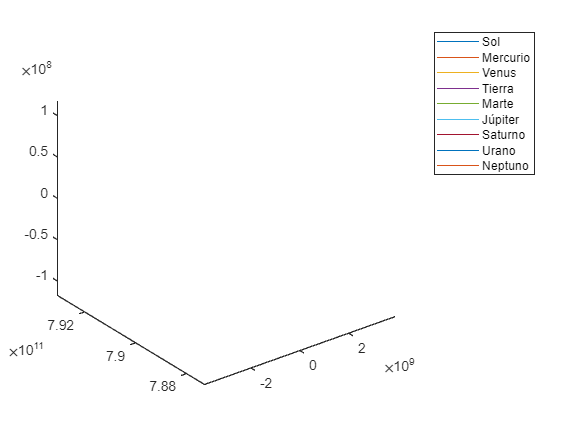


for i=1:3:n/2-2
   
       
    
        plot3(y1(i,:),y1(i+1,:),y1(i+2,:))
    hold on
end
legend("Sol", "Mercurio", "Venus", "Tierra", "Marte", "Júpiter", "Saturno", "Urano", "Neptuno")
hold off

***Distancia mínima***

v1=[y1(1,1),y1(2,1),y1(3,1)];
v2=[y1(4,1),y1(5,1),y1(6,1)];
minDist=norm(v1-v2);
minDay=1;
for i=2:1:366 %ya esta el ajuste de los años en la h, al multiplicarla por 100
    v1=[y1(1,i),y1(2,i),y1(3,i)];
    v2=[y1(4,i),y1(5,i),y1(6,i)];
    dist=norm(v1-v2);
    if dist<=minDist
        minDist=dist;
        minDay=i;
    end
end
fprintf('Mercurio tendrá una distancia mínima de %d', minDist);

Mercurio tendrá una distancia mínima de 4.601709e+10

fprintf('Dicha distancia será el día %d', minDay);

Dicha distancia será el día 62

***Distancia máxima***

v1=[y1(1,1),y1(2,1),y1(3,1)];
v2=[y1(4,1),y1(5,1),y1(6,1)];
maxDist=norm(v1-v2);
maxDay=1;
for i=2:1:366
    v1=[y1(1,i),y1(2,i),y1(3,i)];
    v2=[y1(4,i),y1(5,i),y1(6,i)];
    dist=norm(v1-v2);
    if dist>=maxDist
        maxDist=dist;
        maxDay=i;
    end
end
fprintf('Mercurio tendrá una distancia máxima de %d', maxDist);

Mercurio tendrá una distancia máxima de 6.985824e+10

fprintf('Dicha distancia será el día %d', maxDay);

Dicha distancia será el día 283

distMed=(maxDist-minDist)/2;
fprintf('Mercurio tendrá una distancia media al Sol de %d', distMed);

Mercurio tendrá una distancia media al Sol de 1.192058e+10

### Problema 2

Encontrar cuándo estará Marte más cerca a la Tierra en los próximos 10 años y cuál es esta distancia mínima.

***Vemos la distancia mínima entre Marte y Tierra***

vT=[y1(10,1),y1(11,1),y1(12,1)];
vM=[y1(13,1),y1(14,1),y1(15,1)];
minDist=norm(vT-vM);
minDay=1;
for i=2:1:3650
    vT=[y1(10,i),y1(11,i),y1(12,i)];
    vM=[y1(13,i),y1(14,i),y1(15,i)];
    dist=norm(vT-vM);
    if dist<=minDist
        minDist=dist;
        minDay=i;
    end
end
fprintf('Marte tendrá una distancia mínima a la Tierra de %d', minDist);

Marte tendrá una distancia mínima a la Tierra de 5.761540e+10

fprintf('Dicha distancia será el día %d', minDay);

Dicha distancia será el día 117

## Funciones y métodos que utiliza el programa

function v= aceleracionPlanetas(Gm, Y)

    v=zeros(size(Y));

    v(1:27)=Y((length(Y)/2)+1:end);

    for i=1:3:(length(Y)/2)-2
        v(27+i:27+i+2)=aceleracion(Gm,Y,i);
    end

end

Función aceleración:

function a=aceleracion(Gm, Y, alfa)
    a=zeros(3,1);

    j=1;

    for i=1:3:(length(Y)/2)-2
        if i~=alfa         

            x=Y(i)-Y(alfa);
            y=Y(i+1)-Y(alfa+1);
            z=Y(i+2)-Y(alfa+2);
            r=sqrt(x^2 + y^2 + z^2);

            a=a+[Gm(j)*(x/ r^3);Gm(j)*(y/ r^3);Gm(j)*(z/ r^3)];
        end

        j=j+1;
    end
end

odeRKF45

function [t,y]=odeRKF45(f,t0,tf,y0,h)
   
    i=1;
    t(i)=t0;
    y(:,i)=y0;
    max=1000;
    reTol=10^-6;
    while t(end)<tf && i< max
        [zi,re]=rkf45step(f,t(end),y(:, end),h);
        if re <=reTol
            t(end+1)=t(end)+h;
            y(:,end+1)=zi;
            i=i+1;
        end
        h=0.9*h*nthroot(reTol/re,5);
    end        
end

    function [zi,re] = rkf45step(f,t,w,h) %1 solo paso
        s1=f(t,w);
        s2=f(t+(1/4)*h,w+(1/4)*h*s1);
        s3=f(t+(3/8)*h,w+(3/32)*h*s1+(9/32)*h*s2);
        s4=f(t+(12/13)*h,w+(1932/2197)*h*s1-(7200/2197)*h*s2+(7296/2197)*h*s3);
        s5=f(t+h,w+(439/216)*h*s1-8*h*s2+(3680/513)*h*s3-(845/4104)*h*s4);
        s6=f(t+(1/2)*h,w-(8/27)*h*s1+2*h*s2-(3544/2565)*h*s3+(1859/4104)*h*s4-(11/40)*h*s5);

        wi=w+h*((25/216)*s1+(1408/2565)*s3+(2197/4104)*s4-(1/5)*s5);
        zi=w+h*((16/135)*s1+(6656/12825)*s3+(28561/56430)*s4-(9/50)*s5+(2/55)*s6);
        re=norm((zi-wi)./zi,Inf);
    end

RK4

function [t,y]=RK4_se(f,t0,tf,y0,h)
   
    t=t0:h:tf;
    n=length(t);
    y=zeros(length(y0),n);
    y(:,1)=y0;
    for i=1:n-1
        k1=f(t(i),y(:,i));
        k2=f(t(i)+(h/2),y(:,i)+(h/2)*k1);
        k3=f(t(i)+(h/2),y(:,i)+0.5*k2*h);
        k4=f(t(i)+(h/2),y(:,i)+k2*h);
        phi=(k1+2*k2+2*k3+k4)/6;
        y(:,i+1)=y(:,i)+phi*h;
    end   
end

ABM4

function [t,y]=abm4(f,y0,t0,tf,h)
    t=t0:h:tf;
    n=length(t);
    y=zeros(length(y0) ,n);
    fv=zeros(length(y0),n);
    
    steps=4;
    [t(1:steps),y(:,1:steps)]=RK4_se(f,t0,t0+h*(steps-1),y0,h);
    fv(:,1:steps)=bsxfun(f,t(1:steps),y(:,1:steps)); 

    for i=4:n-1
        
        y(:,i+1)= y(:,i) + (h/24)*( 55*fv(:,i) - 59*fv(:,i-1) + 37*fv(:,i-2) - 9*fv(:,i-3));
        fv(:,i+1)=f(t(i+1),y(:,i+1));
        
        y(:,i+1)=y(:,i) + (h/24)*( 9*fv(:,i+1) + 19*fv(:,i) - 5*fv(:,i-1) + fv(:,i-2));
        fv(:,i+1)=f(t(i+1),y(:,i+1));
    end
end

ABM4 optimizado (ABM4o)

function [t,y]=ABM4o(f,y0,t0,tf,h)
    t=t0:h:tf;
    n=length(t);
    steps=4;
    y=zeros(length(y0) ,n);
    fv=zeros(length(y0),steps);

    [t(1:steps),y(:,1:steps)]=RK4(f,t0,t0+h*(steps-1),y0,h);
    fv(:,1:steps)=bsxfun(f,t(1:steps),y(:,1:steps)); %agarra un valor de la t, y la primer columna del y y aplica la funcion f.

    for i=4:n-1
        %predictor-Adams-Bashford
        y(:,i+1)= y(:,i) + (h/24)*( 55*fv(:,steps) - 59*fv(:,steps-1) + 37*fv(:,steps-2) - 9*fv(:,steps-3));
        fv(:,1:steps-1)=fv(:,2:steps);
        fv(:,steps)=f(t(i+1),y(:,i+1));
        %corrector
        y(:,i+1)=y(:,i) + (h/24)*( 9*fv(:,steps) + 19*fv(:,steps-1) - 5*fv(:,steps-2) + fv(:,steps-3));
        fv(:,steps)=f(t(i+1),y(:,i+1));
    end
end


Minimo y maximo

function [mini,indMin,maxi,indMax]=minMax(t0,tf)
    Gm=[1.32712440018e20;2.2032e13;3.24859e14;3.986044418e14;4.282837e13;1.26686534e17;
    3.7931187e16;5.793939e15;6.836529e15];

    r0=[1.81899e8;9.83630e8;-1.58778e7;
    -5.67576e10;-2.73592e10;2.89173e9;
    4.28480e10;1.00073e11;-1.11872e9;
    -1.43778e11;-4.00067e10;-1.38875e7;
    -1.14746e11;-1.96294e11;-1.32908e9;
    -5.66899e11;-5.77495e11;1.50755e10;
    8.20513e10;-1.50241e12;2.28565e10;
    2.62506e12;1.40273e12;-2.87982e10;
    4.30300e12;-1.24223e12;-7.35857e10];
    v0=[-1.12474e01 ; 7.54876e00 ; 2.68723e-01;
    1.16497e04 ; -4.14793e04 ; -4.45952e03;
    -3.22930e04 ; 1.36960e04 ; 2.05091e03;
    7.65151e03; -2.87514e04 ; 2.08354e00;
    2.18369e04 ; -1.01132e04 ; -7.47957e02;
    9.16793e03 ; -8.53244e03 ; -1.69767e02;
    9.11312e03 ; 4.96372e02 ; -3.71643e02;
    -3.25937e03 ; 5.68878e03 ; 6.32569e01;
    1.47132e03 ; 5.25363e03 ; -1.42701e02];

    y0=[r0;v0];
    h=60*60*24;
    fPlanetas=@(t,y)aceleracionPlanetas(Gm,y);
    tfOde=h*365*tf;
    [t,y]=RK4_se(fPlanetas,0,tfOde,y0,h);
    
    n=length(y(1,:));
    dST=zeros(3,n);
    dSL=zeros(3,n);
    dTL=zeros(3,n);
    for i=1:3
        dST(i,:)=y(i,:)-y(3+i,:);
        dSL(i,:)=y(i,:)-y(6+i,:);
        dTL(i,:)=y(3+i,:)-y(6+i,:);
    end
    mini=zeros(3,1);
    indMin=zeros(3,1);
    maxi=zeros(3,1);
    indMax=zeros(3,1);
    [mini(1),indMini(1)]=min(norm([dST(1,:),dST(2,:),dST(3,:)]));
end